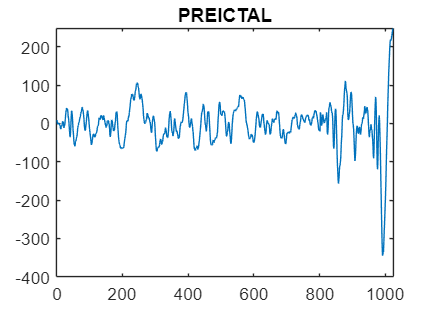

clc
clear
close all
tic
data= load("C:\Users\preet\OneDrive\Desktop\BVB\DSP\EEG Epilepsy Datasets\preictal\preictal1.mat");
figure
plot(data.preictal(:,1));
title("PREICTAL");

N=length(data.preictal(:,1));
x=data.preictal(:,1);
X=[];
g=[];
h=[];
a=0;
b=0;

p = nextpow2(length(x)); % determining the length closest to the power of 2
padding_length = 2^p - length(x); % calculate the required padding length
if padding_length > 0
    x = [x zeros(padding_length, 1)]; % pad with zeros if necessary
end
N=length(x)

N = 1024

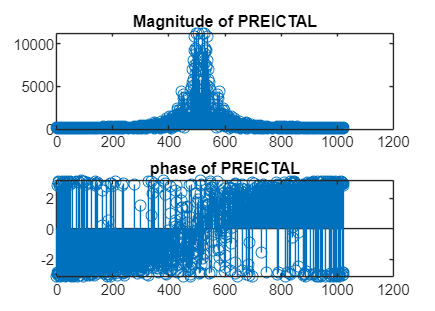


for n=1:N/2
    g(n)=x(n)+x(n+N/2);
end

for n=1:N/2
    b=x(n)-x(n+N/2);
    h(n)=b*exp(-j*2*pi*(n-1)/N);
end


for k=1:N/2
    for n=1:N/2
        a = a + g(n)*exp(-j*4*pi*(n-1)*(k-1)/N);
    end
    X(2*k-1)=a;
    a=0;
end

for k=1:N/2
    for n=1:N/2
        a = a + h(n)*exp(-j*4*pi*(n-1)*(k-1)/N);
    end
    X(2*k)=a;
    a=0;
end

mag_X = abs(X);
    phi_X = angle(X);
    z1 = fftshift(mag_X);
    z2 = fftshift(phi_X);

    figure;
    subplot(2, 1, 1);
    stem(z1);
    title('Magnitude of PREICTAL');
  
    subplot(2, 1, 2);
    stem(z2);
    title('phase of PREICTAL');

toc

Elapsed time is 0.938684 seconds.
